# A von Karman plate with 1:1 internal resonance

In this example, we consider a simply-supported von Karman square plate subject to harmonic excitation. Due to the geometric symmetry, the natural frequenices of the second and the third modes are the same. In other words, the system has 1:1 internal resonance between the two modes. We extract the forced response curve using SSM reduction. 

## Geometry and finite element model

We discretize the plate with 200 elements and then 606 degrees-of-freedom. The dimension of the phase space of the full system is then 1212. As we will see, the reduced-order model obtained by SSM reduction is four dimensional.

Building FE model
Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem
The circular natural frequencies of the first five modes:


omega = 1.0e+03 *

    0.3067
    0.7636
    0.7677
    1.2188
    1.5311


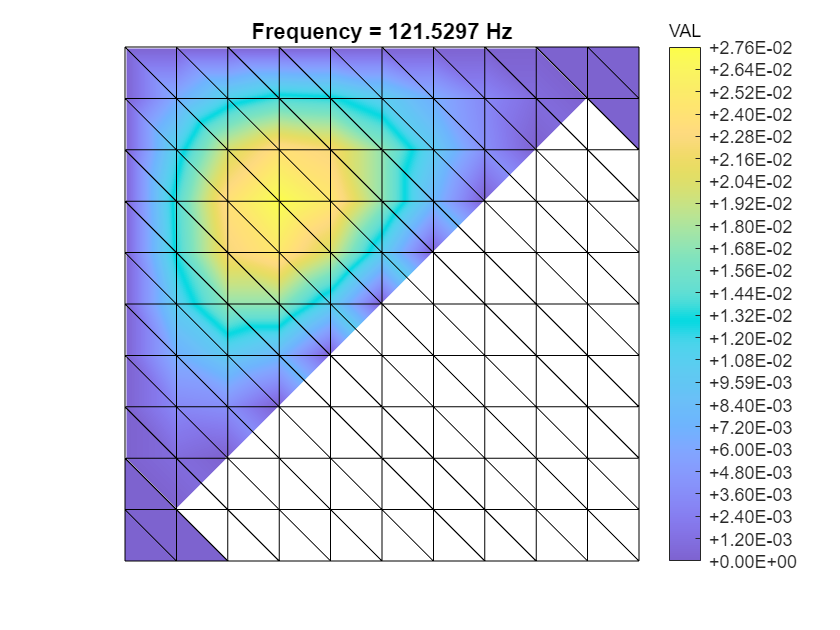

Using Rayleigh damping
Getting nonlinearity coefficients
Loaded tensors from storage
Assembling external force vector


clear all; close all; clc

l = 1; % length of domain [m]
b = 1;  % breadth of domain [m]
t = 1e-2; % thickness of plate [m]
w = 0.0; % curvature parameter (height of the midpoint relative to ends) [m]
% material properties
E     = 70e9;  % 70e9 % 200e9 % Young's modulus [Pa]
rho   = 2700; % 2700 % 7850 % density [kg/m^3]
nu    = 0.33;    % Poisson's ratio 
kappa = 1e5; % material damping modulus 1e8

% Mesh
nElements = 10;
nl = nElements;
nb = nElements;
bc = 'SSSS';
startFE = tic;
[M,C,K,fnl,~,outdof] = build_model(l,b,t,w,E,rho,nu,kappa,bc,nl,nb);

timeFE = toc(startFE);
varargout{1} = timeFE;
n  = length(M);

## Dynamical System Setup

notation = 'multiindex';
DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation',notation);

## Linear Modal analysis

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.243693e-03
modal damping ratio for 2 mode is 2.181986e-03
modal damping ratio for 3 mode is 2.186754e-03
modal damping ratio for 4 mode is 2.847788e-03
modal damping ratio for 5 mode is 3.388843e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 10 nonzero eigenvalues are given as 
   1.0e+03 *

  -0.0007 + 0.3067i
  -0.0007 - 0.3067i
  -0.0017 + 0.7636i
  -0.0017 - 0.7636i
  -0.0017 + 0.7677i
  -0.0017 - 0.7677i
  -0.0035 + 1.2188i
  -0.0035 - 1.2188i
  -0.0052 + 1.5311i
  -0.0052 - 1.5311i



## Add forcing

f_0 = zeros(n,1);
f_0(outdof(1)) = 100*1e-2;
kappas  = [-1; 1];
epsilon = 50;
coeffs  = [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas, epsilon);

## Primiary resonance with IRs

**Create SSM**

S = SSM(DS);
set(S.Options, 'reltol', 0.8,'notation',notation); % 0.8 is used

**Extract FRC**

Recall that the natural frequencies of the linear modes are given by


$$\omega_{(i,j)}=\left(\frac{i^2}{l^2}+\frac{j^2}{b^2}\right)\pi^2\sqrt{\frac{D}{\rho t}}$$


where $D$ is the bending stiffness. Given $l=b$, we have $\omega_{(1,2)}=\omega_{(2,1)}$, namely the 1:1 internal resonance between the second and the third bending modes. In addition, we have $\omega_{(3,1)}=\omega_{(1,3)}=2\omega_{(1,2)}$, which implies that the higher modes (1,3) and (3,1) will also be taken as a part of the spectral subspace in the extract_FRC routine. Here we are mainly concerned with the 1:1 internal resonance. So we need to specify the spectral subspace, which can be easily done in the SSM-ep toolbox.

(near) outer resonance detected for the following combination of master eigenvalues
     0     0     1     1
     0     1     1     0
     1     0     0     1
     1     1     0     0
     0     0     2     1
     0     1     2     0
     1     0     1     1
     1     1     1     0
     2     0     0     1
     2     1     0     0
     0     0     1     1
     0     1     1     0
     1     0     0     1
     1     1     0     0
     0     0     1     2
     0     1     1     1
     0     2     1     0
     1     0     0     2
     1     1     0     1
     1     2     0     0
     0     0     2     0
     1     0     1     0
     2     0     0     0
     0     0     2     1
     0     1     2     0
     1     0     1     1
     1     1     1     0
     2     0     0     1
     2     1     0     0
     0     0     0     2
     0     1     0     1
     0     2     0     0
     0     0     1     2
     0     1     1     1
     0     2     1     0
     1     0     0     2
     1     1    

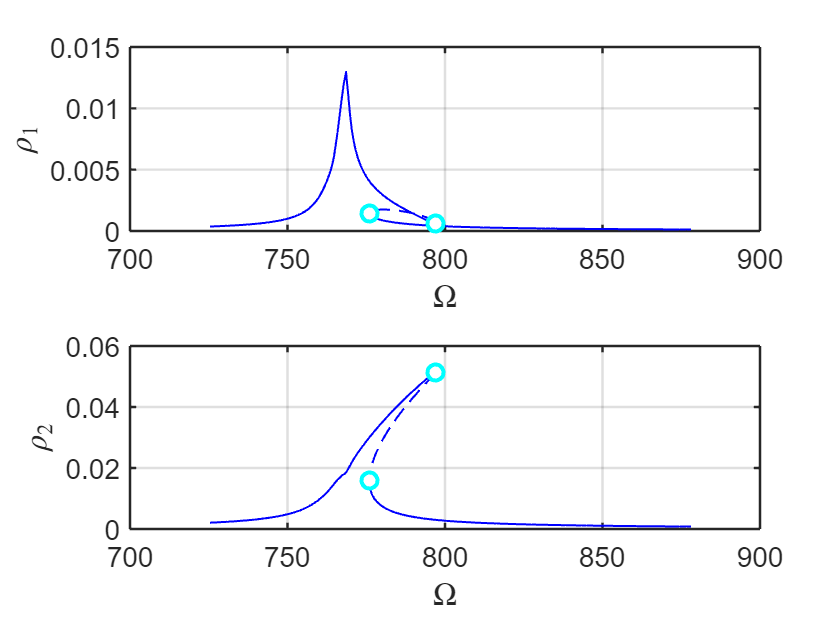

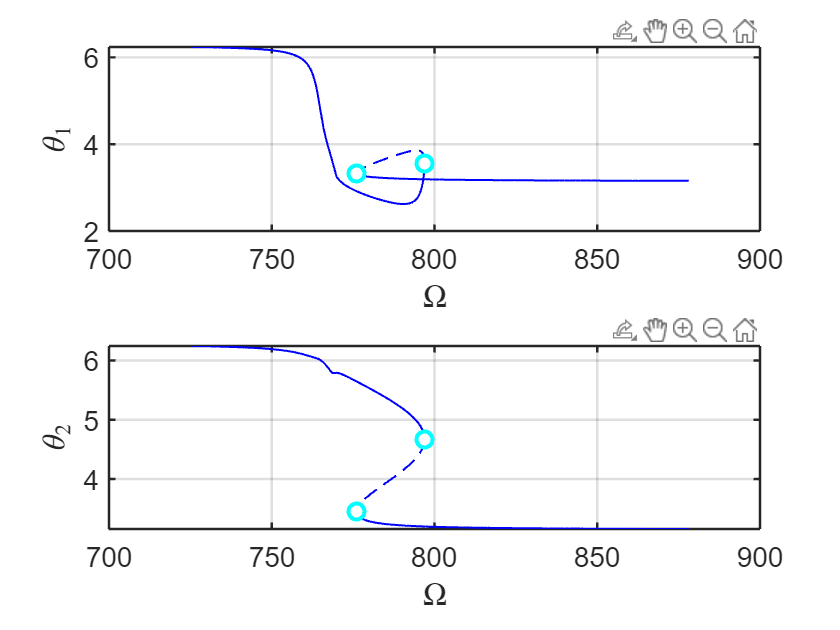

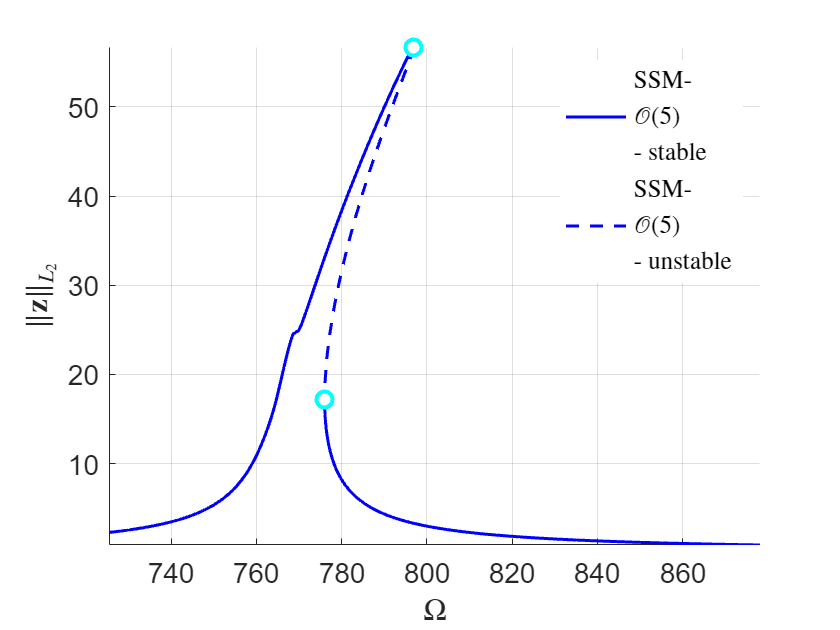

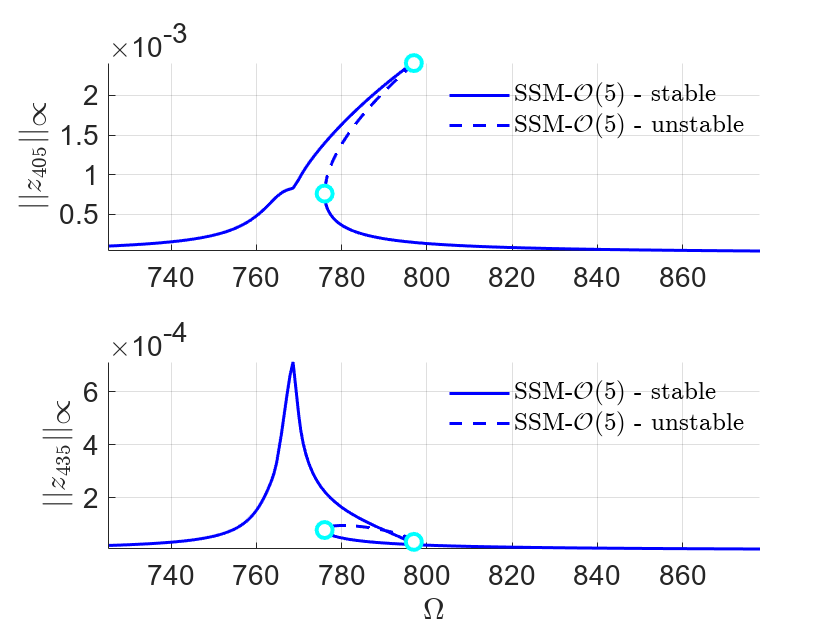

set(S.contOptions, 'PtMX', 2500, 'h_max', 5, 'h_min', 1e-4);
set(S.FRCOptions, 'initialSolver', 'fsolve');
freqrange = [0.95 1.15]*imag(D(3));
order     = 5;
resonant_modes = [3 4 5 6];
mFreq   = [1 1];
set(S.Options, 'contribNonAuto',false, 'COMPtype', 'first');
p0 = [730 50]';
z0 = [1e-3 0 1e-3 0]';
FRC_lead = S.SSM_isol2ep('isol_polar_V2',resonant_modes, order, mFreq, 'freq', freqrange,outdof,{p0,z0});

**Extract FRS**

(near) outer resonance detected for the following combination of master eigenvalues
     0     0     1     1
     0     1     1     0
     1     0     0     1
     1     1     0     0
     0     0     2     1
     0     1     2     0
     1     0     1     1
     1     1     1     0
     2     0     0     1
     2     1     0     0
     0     0     1     1
     0     1     1     0
     1     0     0     1
     1     1     0     0
     0     0     1     2
     0     1     1     1
     0     2     1     0
     1     0     0     2
     1     1     0     1
     1     2     0     0
     0     0     2     0
     1     0     1     0
     2     0     0     0
     0     0     2     1
     0     1     2     0
     1     0     1     1
     1     1     1     0
     2     0     0     1
     2     1     0     0
     0     0     0     2
     0     1     0     1
     0     2     0     0
     0     0     1     2
     0     1     1     1
     0     2     1     0
     1     0     0     2
     1     1    

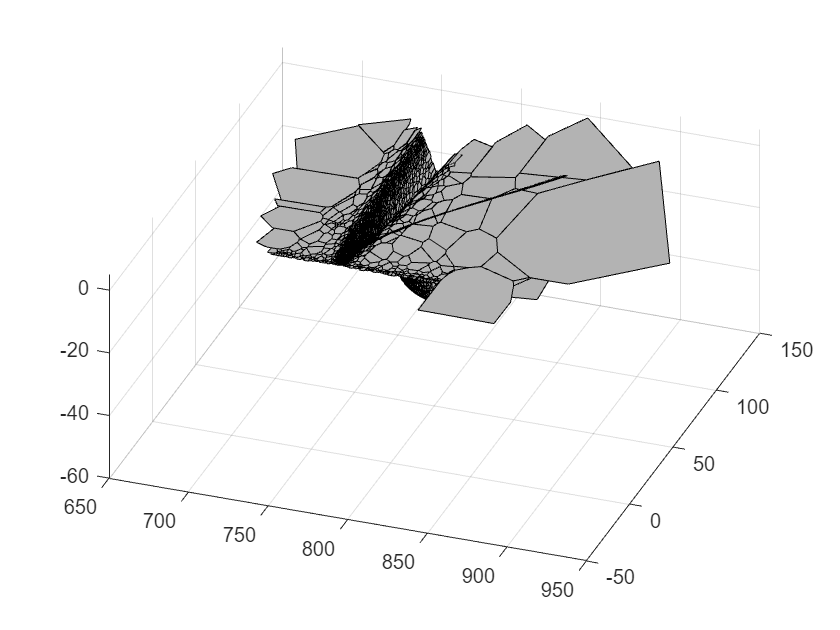

epsRange = [1 100];
set(S.contOptions,'atlasdim',2, 'R', 2,'R_max',100,'R_min',1e-4,'almax',15,'PtMX',10000); %10000 
set(S.FRCOptions, 'coordinates', 'cartesian');
parRange = {freqrange,epsRange};
p0 = [750 30]';
z0 = [1e-3 0 1e-3 0]';

optdof = [outdof; (n+1:2*n)'];
wmat = blkdiag(zeros(2),M/2);
set(S.FRCOptions,'DBCobjweight',wmat); % for kinetic energy
set(S.Options, 'COMPtype', 'first'); set(S.FRSOptions, 'calFRS', true);
scale_states = [1000 1000 1000 1000];
scale_obs    = [10; 1e4*ones(2*numel(outdof),1)];
startfrs = tic;
S.extract_FRS('plate_scale',resonant_modes,order,mFreq,parRange,outdof,optdof,scale_states,scale_obs,{p0,z0});

timings.FRS = toc(startfrs);

plot results

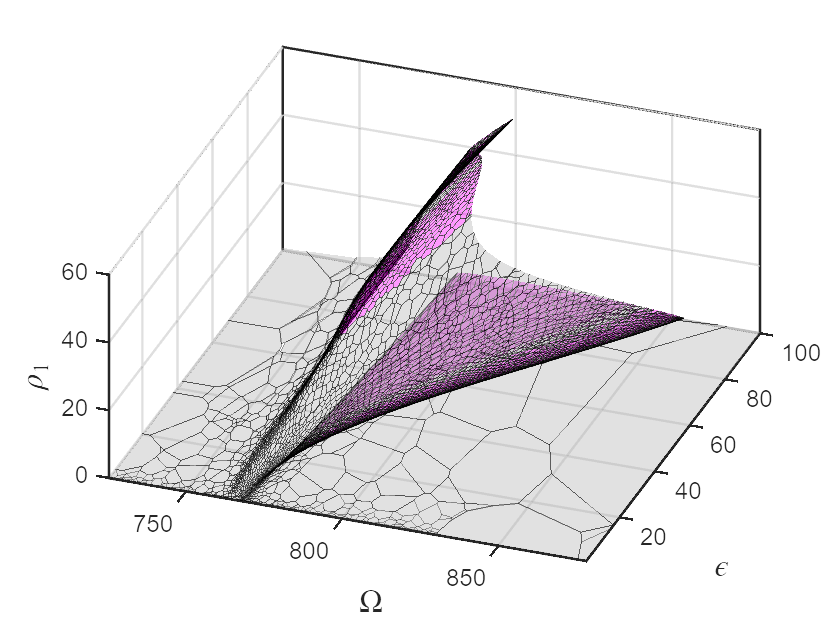

runid = 'plate_scale.FRSep';
figure;
plot_atlas_2d(runid, 1, 2, 12);
xlim(freqrange); ylim(epsRange);
xlabel('$\Omega$','FontSize',16,'Interpreter',"latex");
ylabel('$\epsilon$','FontSize',16,'Interpreter',"latex");
zlabel('$\rho_1$','FontSize',16,'Interpreter',"latex");

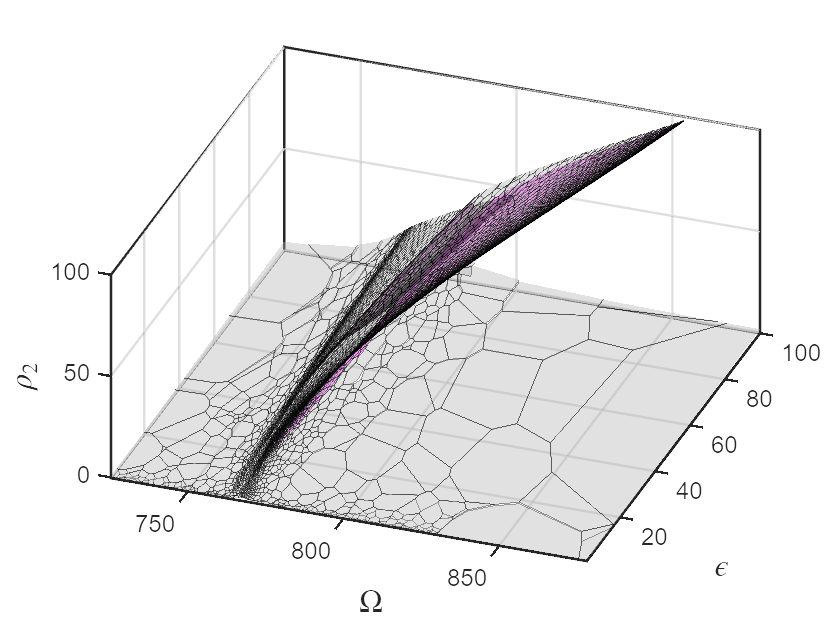

% saveas(gcf,'plate_frs_rho1');

figure;
plot_atlas_2d(runid, 1, 2, 13);
xlim(freqrange); ylim(epsRange);
xlabel('$\Omega$','FontSize',16,'Interpreter',"latex");
ylabel('$\epsilon$','FontSize',16,'Interpreter',"latex");
zlabel('$\rho_2$','FontSize',16,'Interpreter',"latex");

% saveas(gcf,'plate_frs_rho2');

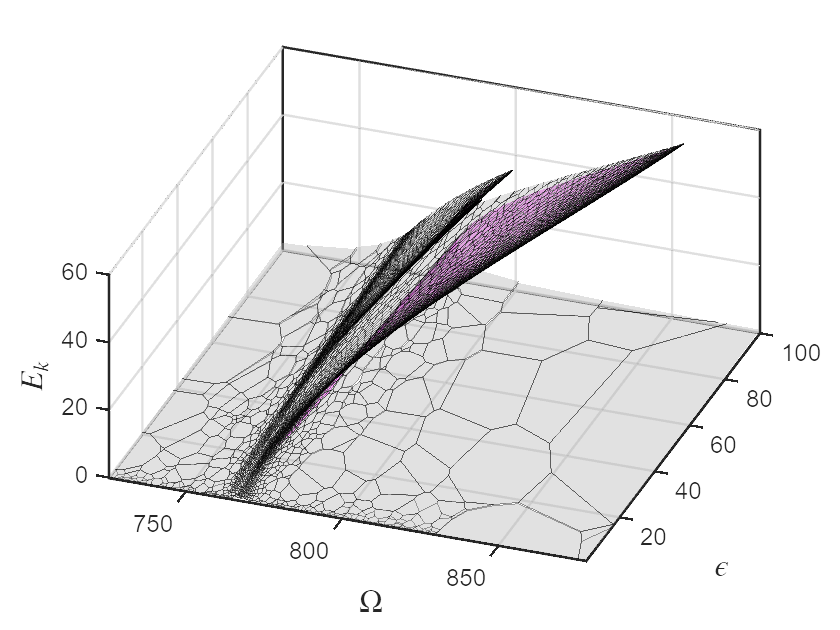

figure;
plot_atlas_2d(runid, 1, 2, 7);
xlim(freqrange); ylim(epsRange);
xlabel('$\Omega$','FontSize',16,'Interpreter',"latex");
ylabel('$\epsilon$','FontSize',16,'Interpreter',"latex");
zlabel('$E_k$','FontSize',16,'Interpreter',"latex");

% saveas(gcf,'plate_frs_Ek');

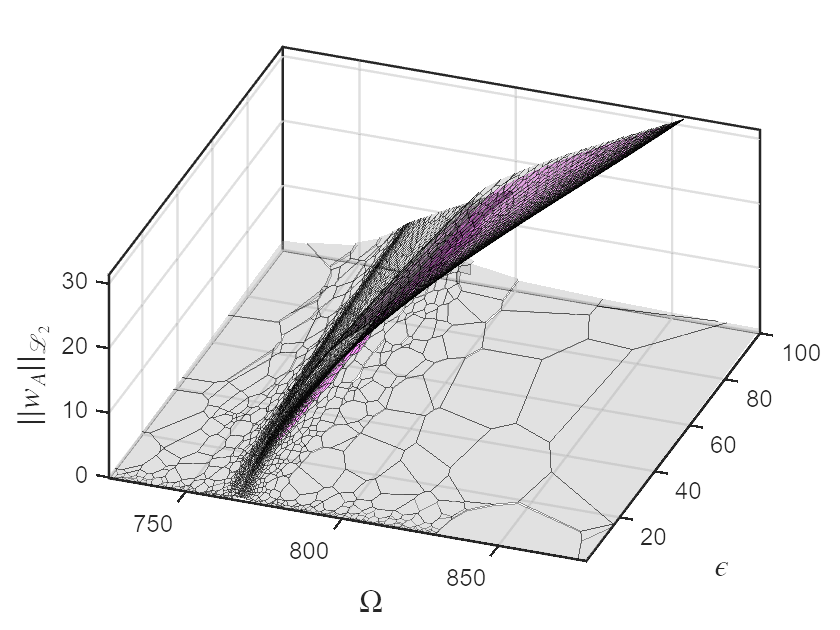

figure;
plot_atlas_2d(runid, 1, 2, 8);
xlim(freqrange); ylim(epsRange);
xlabel('$\Omega$','FontSize',16,'Interpreter',"latex");
ylabel('$\epsilon$','FontSize',16,'Interpreter',"latex");
zlabel('$||w_A||_{\mathcal{L}_2}$','FontSize',16,'Interpreter',"latex");

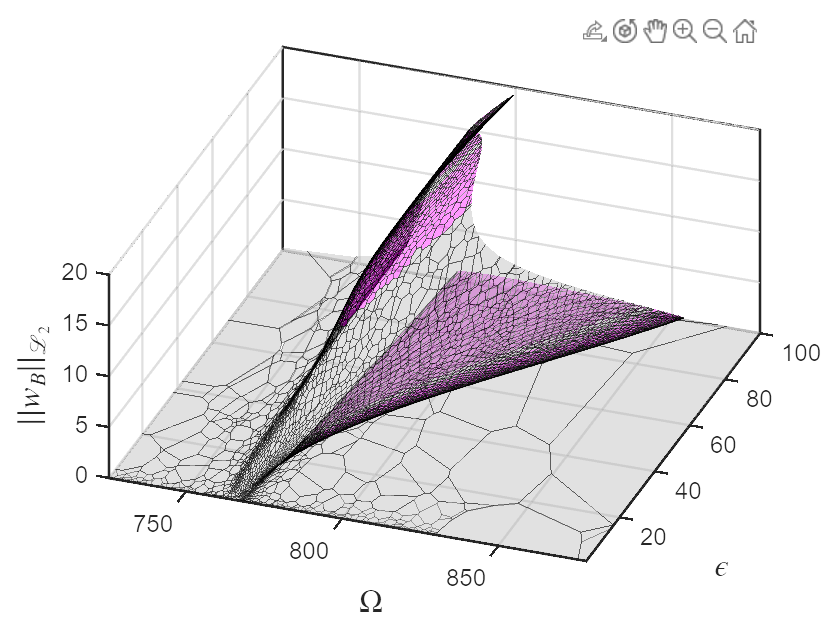

% saveas(gcf,'plate_frs_wa_l2');

figure;
plot_atlas_2d(runid, 1, 2, 9);
xlim(freqrange); ylim(epsRange);
xlabel('$\Omega$','FontSize',16,'Interpreter',"latex");
ylabel('$\epsilon$','FontSize',16,'Interpreter',"latex");
zlabel('$||w_B||_{\mathcal{L}_2}$','FontSize',16,'Interpreter',"latex");

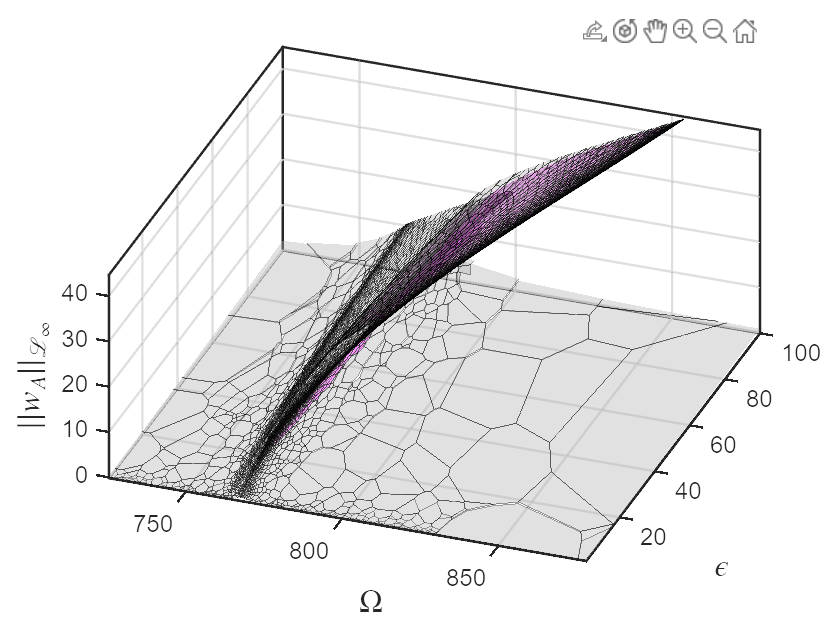

% saveas(gcf,'plate_frs_wb_l2');

figure;
plot_atlas_2d(runid, 1, 2, 10);
xlim(freqrange); ylim(epsRange);
xlabel('$\Omega$','FontSize',16,'Interpreter',"latex");
ylabel('$\epsilon$','FontSize',16,'Interpreter',"latex");
zlabel('$||w_A||_{\mathcal{L}_\infty}$','FontSize',16,'Interpreter',"latex");

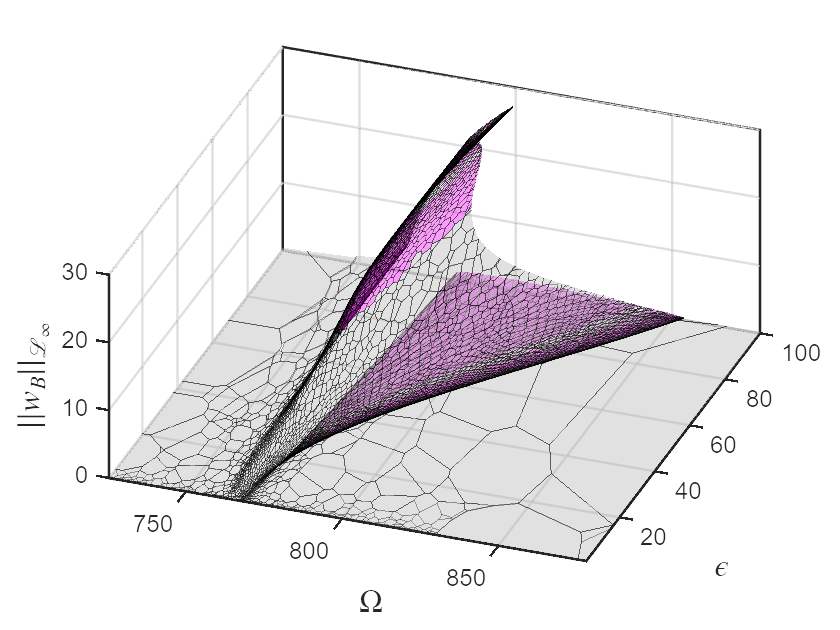

% saveas(gcf,'plate_frs_wa_linf');

figure;
plot_atlas_2d(runid, 1, 2, 11);
xlim(freqrange); ylim(epsRange);
xlabel('$\Omega$','FontSize',16,'Interpreter',"latex");
ylabel('$\epsilon$','FontSize',16,'Interpreter',"latex");
zlabel('$||w_B||_{\mathcal{L}_\infty}$','FontSize',16,'Interpreter',"latex");

% saveas(gcf,'plate_frs_wb_linf');